# **PESTools - Example 022 - Simulating the photoelectron intensity contributions of an N-layered sample**

## PCC

This example shows how to use PESTools to simulate the photoelectron intensity contributions of an N-layered sample as a function of photon energy. This can be used to model experimental data obtained at ADRESS; XPS data as a function of photon energy. The function used in this example is the 'nlayer_pes_model()' function, which is quite considerable in it's scope. The function allows you to define the material type of each layer, the thickness, the core-level being probed and then determines the emitted photoelectron intensity of each layer using the Beer-Lambert law. All the material, photoionisation and core-level parameters are stored within multiple databases within the Github directory, put together by PCC.

We use the following databases here to make the initial setup of the N-layered sample user friendly:

- **Material Properties Database (MPD):** Atomic symbols, Z numbers, atomic / compound weights, electronegativity, electron affinity, ionisation energies, temperatures, crystal structures, unit cell parameters, band-gaps, work functions, electronic and magnetic properties.

material_props = get_mpd_props('U')

material_props = 1×42 table
    ID       TYPE         ATOM_NAME     ATOM_SYMB    ATOM_ZNUM    ATOM_MASS    ATOM_RADIUS    ATOM_TERM        ELECT_CONFIG        ELECT_VALENCY    ELECT_NEGATIVITY    ELECT_AFFINITY    ELECT_FIRST_IONISATION    NEUT_NUM    NEUT_XSECT    NEUT_MASS_ABSORB       RADACVTY        PHASE_RT     SPEC_HEAT    T_SUPER    T_CURIE    T_NEEL    T_MELT    T_BOIL    T_CRIT      CRY_STRUCT      CRY_A     CRY_B     CRY_C     CRY_ALPHA    CRY_BETA    

- **Photoionisation Cross-Section and Asymmetry Database (PIXSAD):**  This database contains all the photoionisation cross-sections and asymmetry parameters for elements 1 - 103, for orbitals that are probed with soft x-ray radiation (20 - 1500 eV). 

[hv, xsect, asymmetry] = get_pixsad_props('U', [], 950:1500)

hv = 551×1 table
    hv 
    ___
    950
    951
    952
    953
    954
    955
    956
    957
    958
    959
    960
    961
    962
    963
    964
    965

xsect = 551×10 table
    4s-sig    4p-sig    4d-sig     4f-sig     5s-sig      5p-sig     5d-sig      5f-sig      6p-sig      6d-sig  
    ______    ______    _______    ______    ________    ________    _______    ________    ________    _________
     NaN       NaN      0.63553    2.1437    0.033267    0.093173    0.16207    0.037187    0.016873    0.0015127
     NaN       NaN      0.63518    2.1389     0.03321    0.093035    0.16185    0.037107    0.016848    0.0015105
     NaN       NaN      0.63483    2.1342    0.033153    0.092898    0.16163    0.037028    0.016822    0.0015084
     NaN       NaN      0.63447    2.1295    0.033096    0.092761    

asymmetry = 551×10 table
    4s-beta    4p-beta    4d-beta    4f-beta    5s-beta    5p-beta    5d-beta    5f-beta    6p-beta    6d-beta
    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______
      NaN        NaN       0.1441    0.65343       2       1.5927     1.1467     0.96327    1.6587     1.2267 
      NaN        NaN      0.14742    0.65431       2        1.593     1.1473     0.96365    1.6589     1.2272 
      NaN        NaN      0.15073    0.65518       2       1.5934     1.1479     0.96403    1.6591     1.2276 
      NaN        NaN      0.15403    0.65605       2       1.5937     1.1486    

- **Photoionisation Energy and Fluorescence Database (PIEFD):**  This database contains all the binding energies, emission / fluorescence lines, emission / fluorescence relative intensities and fluorescence yield.

piefd_props = get_piefd_props('U')

piefd_props = 1×52 table
    ID     ATOM_NAME     ATOM_SYMB    ATOM_ZNUM        ELECT_CONFIG           BE_K       BE_L1    BE_L2    BE_L3    BE_M1    BE_M2    BE_M3    BE_M4    BE_M5    BE_N1    BE_N2    BE_N3    BE_N4    BE_N5    BE_N6    BE_N7    BE_O1    BE_O2    BE_O3    BE_O4    BE_O5    BE_P1    BE_P2    BE_P3    FLUO_PE_K_L3    FLUO_PE_K_L2    FLUO_PE_K_M3    FLUO_PE_L3_M5    FLUO_PE_L3_M4    FLUO_PE_L2_

Once you define the N-layered sample, the photoelectron contributions of each layer is determined as followed:

**(1) The N-layered sample is first plotted and labelled to ensure it is defined correctly.**

**(2) Determination of the IMFP at all kinetic energies for each layer material:**

- Extract the **binding energy**, $E_B$, for each layer material core-level that is probed from the **PIEFD**.

- Extract the **work function**, $\Phi$, for each layer material from the **MPD**.

- Determine the **kinetic energy**, $E_k$, of photoelectrons for each layer material; $E_k =h\nu \;-E_B -\Phi \;$.

- Determine the **IMFP,** $\lambda_i \;$, at **all** kinetic energies for **each** layer material; the relativistic TPP-2M formalism is used to determine the IMFP.

**(3) Determine the maximum intensity **$I_0$** for each layer material: **$I_i =N_i \;F_i$.

- Determine the** total number of atoms per unit volume**, $N_i \;$, for each layer; $N_i =N_A \rho /M\;$. The **density**, $\rho$, and **atomic weight**, $M$, for each layer material is found in the **MPD**. $N_A$is the Avogadro constant.

- Extracting the **photoionisation cross section**, $\sigma_i$, for each layer, which depends on the photon energy and core-level being probed. These values are found in the **PIXSAD**.

- Extract the **asymmetry factor** ${\beta \;}_i$, for each layer, which strongly depends on the angular momentum number of the core-level being probed. These values are found in the **PIXSAD**.

- Determine the **adjusted asymmetry factor** ${\beta \;}_i^*$, which accounts for randomised elastic scattering in a solid material; ${\beta \;}_i^* =\beta \;\left(a-\textrm{bZ}+{\textrm{cZ}}^2 \right)$, where $a=0\ldotp 781,\;b=0\ldotp 00514,c=0\ldotp 000031,Z=\textrm{average}\;Z\;\textrm{number}\;\textrm{of}\;\textrm{all}\;\textrm{layers}\ldotp$

- Determine the **angular correction** **factor; **$L\left({\beta \;}_i^* ,\gamma {\;}_i \right)=1+0\ldotp 5{\beta \;}_i^* \left(1\ldotp 5\sin^2 \gamma -1\right)$, where $\gamma$is the angle between the incident x-rays and the analyser.

- Determine the **relative sensitivity factor, **$F_i$, which is: $F_i =\sigma_i \;L\left({\beta \;}_i^* ,\gamma {\;}_i \right)\;\lambda_i$.

- Finally, determine$\;I_{0,i} =N_i \;F_i$, which gives the **maximum intensity of each photoelectron component without any mitigation through the N-layered sample.**

**(4) Use the Beer-Lambert law to model the attenuation of the photoelectron intensity.**

- This model states that the photoelectron intensity decreases exponentially due to inelastic scattering, with a decay constant equal to the $\lambda_i$. 

- Thus, for a bulk, single-layer system, the Beer-Lambert law states: $I\left(z\right)=I_0 \;\exp \left(-z/\lambda \cos \theta \right)$, which gives the **photoelectron intensity**,$I$, that emerges from a **depth**, $z$, within the sample. Propagating this equation to each layer in the sample defined by the user, allows the total integral intensity of each photoelectron component for each layer in the sample stack to be determined. This is then normalised in terms of a 'relative contribution', whereby each layer is divided by the total sum of all intensities at each photon energy.

- For a 2 model system, the equations are:  $I_{\textrm{OL}} =I_{0,\textrm{OL}} \;\left(1-\exp \left(-d_{\textrm{OL}} /\lambda_{\textrm{OL}} \cos \theta \right)\right)\;\;\;\;\;\;\textrm{and}\;\;\;\;\;\;\;\;\;I_{\textrm{BULK}} =I_{0,\textrm{BULK}} \;\exp \left(-d_1 /\lambda_1 \cos \theta \right)\;$

We will now go through an example to demonstrate how to use this to solve your own problems.

close all; clear all;

# **Example models**

## (1) A 2-layer model (typical for oxides grown on a substrate)

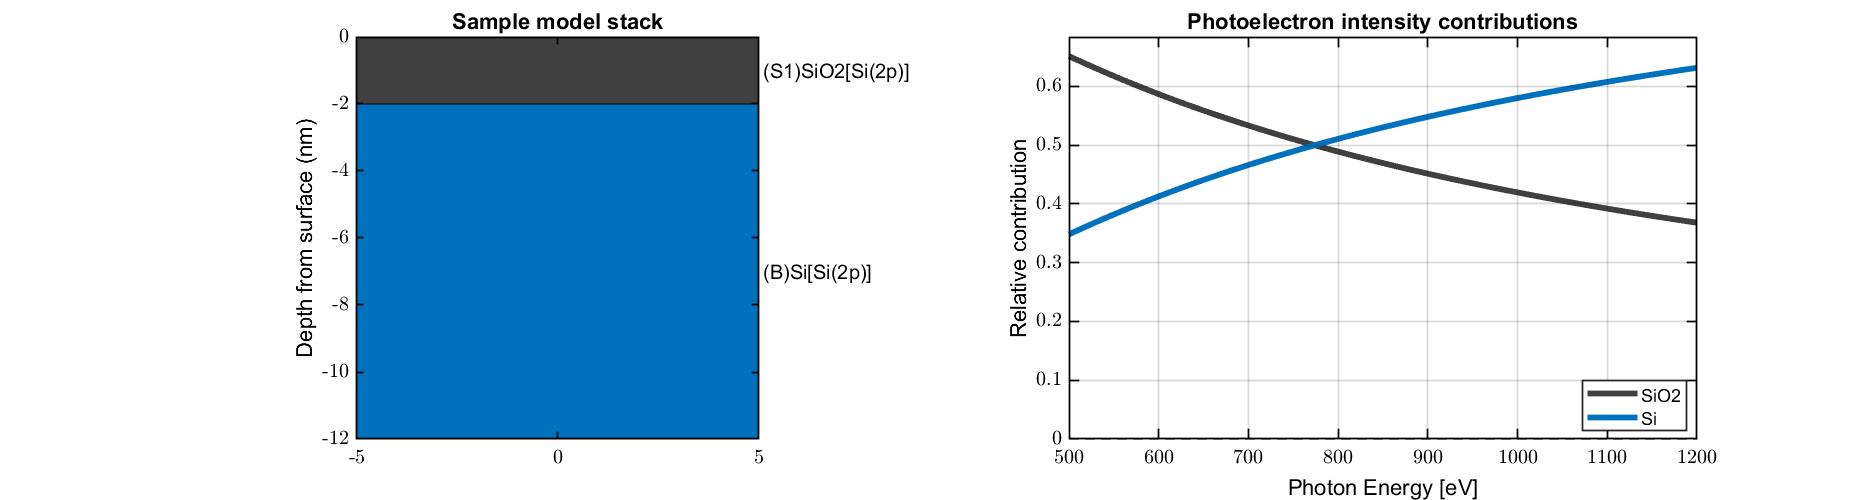

pes_hv          = linspace(500, 1200, 1e3);     % Defining the incident photon energy
lyr_mat         = {'SiO2', 'Si'};               % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Si(2p)', 'Si(2p)'};         % Defining the core-level being probed for each layer.
lyr_thick       = {2.0, Inf};                   % Defining the thickness of each layer. For a 2-layer model system, only the upper layer matters, as the last layer is always considered as the bulk.
pes_model_2     = nlayer_pes_model(pes_hv, lyr_mat, lyr_cls, lyr_thick);

## (2) A 4-layer model (an ultra-shallow dopant delta-layer in silicon)

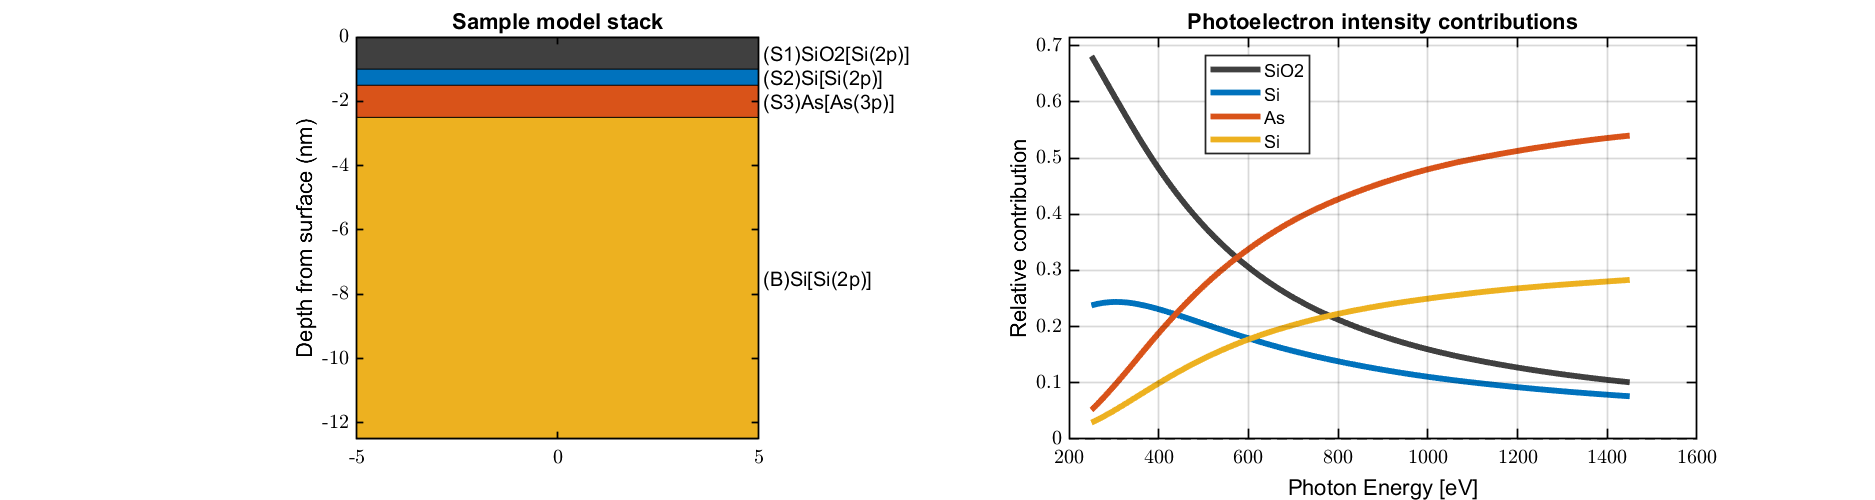

pes_hv          = linspace(250, 1450, 1e3);                     % Defining the incident photon energy
lyr_mat         = {'SiO2', 'Si', 'As', 'Si'};                   % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Si(2p)', 'Si(2p)', 'As(3p)', 'Si(2p)'};     % Defining the core-level being probed for each layer.
lyr_thick       = {1.0, 0.5, 1.0, Inf};                         % Defining the thickness of each layer.
pes_model_4     = nlayer_pes_model(pes_hv, lyr_mat, lyr_cls, lyr_thick);

## (3) A 5-layer model (a complicated structure just to demonstrate the maximum number of layers that can be used)

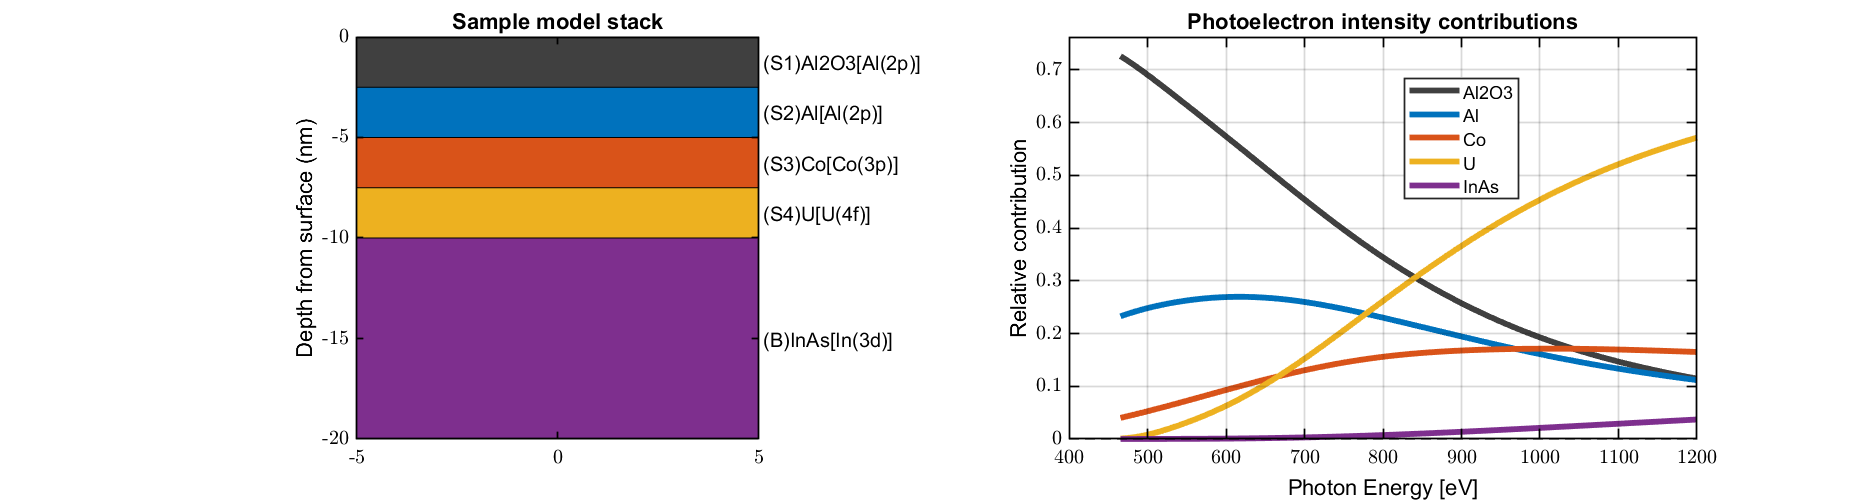

pes_hv          = linspace(100, 1200, 1e3);                                 % Defining the incident photon energy
lyr_mat         = {'Al2O3', 'Al', 'Co', 'U', 'InAs'};                       % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Al(2p)', 'Al(2p)', 'Co(3p)', 'U(4f)', 'In(3d)'};        % Defining the core-level being probed for each layer.
lyr_thick       = {2.5, 2.5, 2.5, 2.5, Inf};                                % Defining the thickness of each layer.
pes_model_5     = nlayer_pes_model(pes_hv, lyr_mat, lyr_cls, lyr_thick);

# **Useful miscellaneous functions after solving the model**

**(1) Plotting the sample model stack and photoelectron intensity contributions**

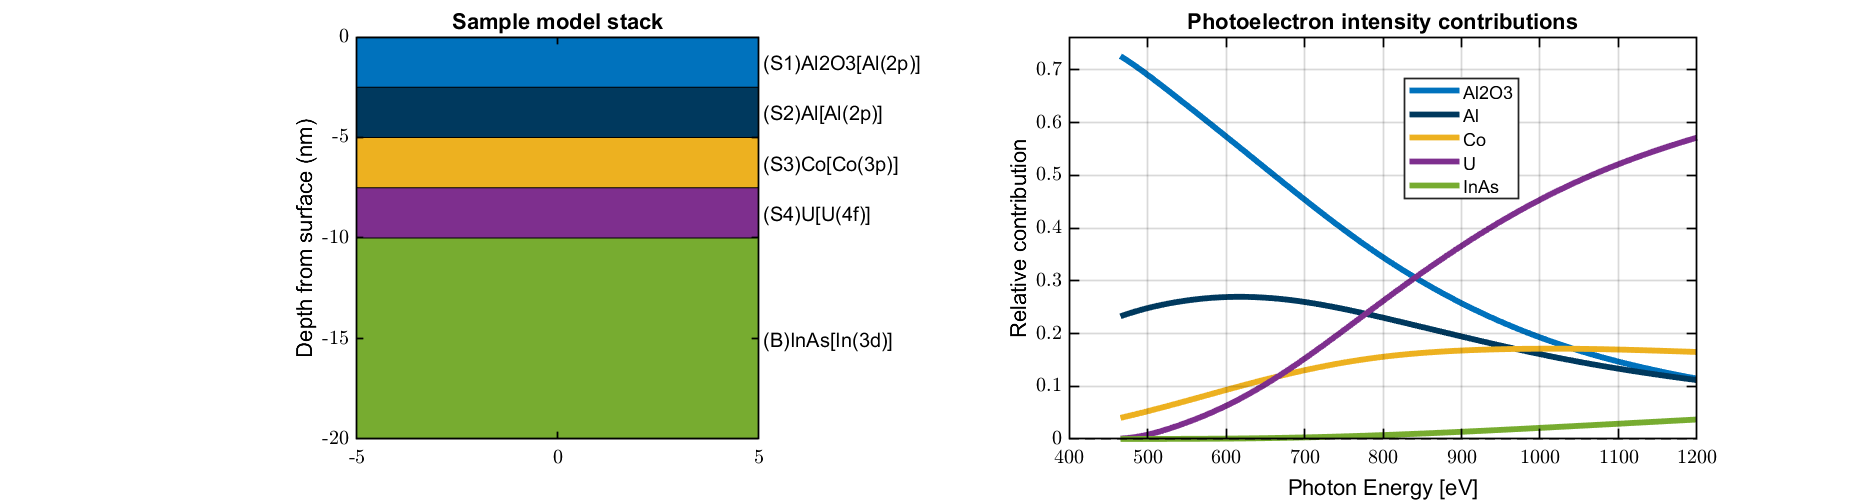

pes_hv          = linspace(100, 1200, 1e3); 
pp  = plot_props();
% -- Plotting the full PES model (sample and photoelectron intensity contributions)
fig = view_nlayer_pes_model(pes_model_5, {pp.col.fit{2}, 0.5*pp.col.fit{2}, pp.col.fit{4}, pp.col.fit{5}, pp.col.fit{6}});

**(2) Plotting a generic n-layered sample stack**

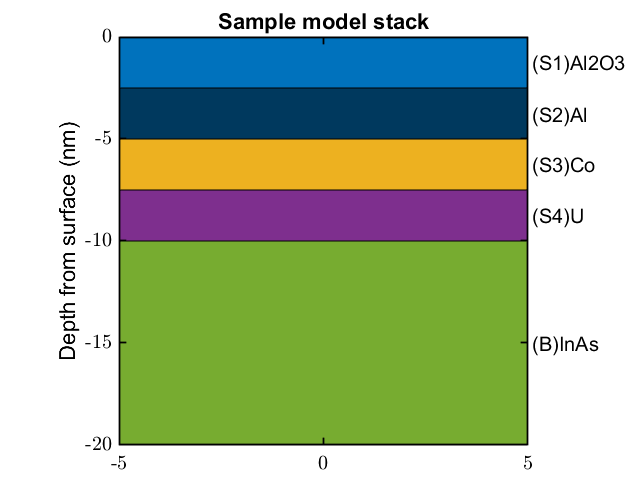

lyr_mat         = {'Al2O3', 'Al', 'Co', 'U', 'InAs'};
lyr_thick       = {2.5, 2.5, 2.5, 2.5, Inf};
lyr_cols        = {pp.col.fit{2}, 0.5*pp.col.fit{2}, pp.col.fit{4}, pp.col.fit{5}, pp.col.fit{6}};
fig             = view_nlayer_sample(lyr_mat, lyr_thick, lyr_cols);